# Actividad 6.2 (Comparación de Algoritmos de Control)

## Daniel Castillo López

## A01737357

- **Implementar** el código requerido para generar el seguimiento de la siguiente trayectoria con un robot tipo diferencial aplicando las técnicas: “**Lazo abierto**”, “**Lazo cerrado con posiciones deseadas**” (Control de Posición) y “**Lazo cerrado con posiciones y velocidades deseadas**” (Control de Trayectoria)

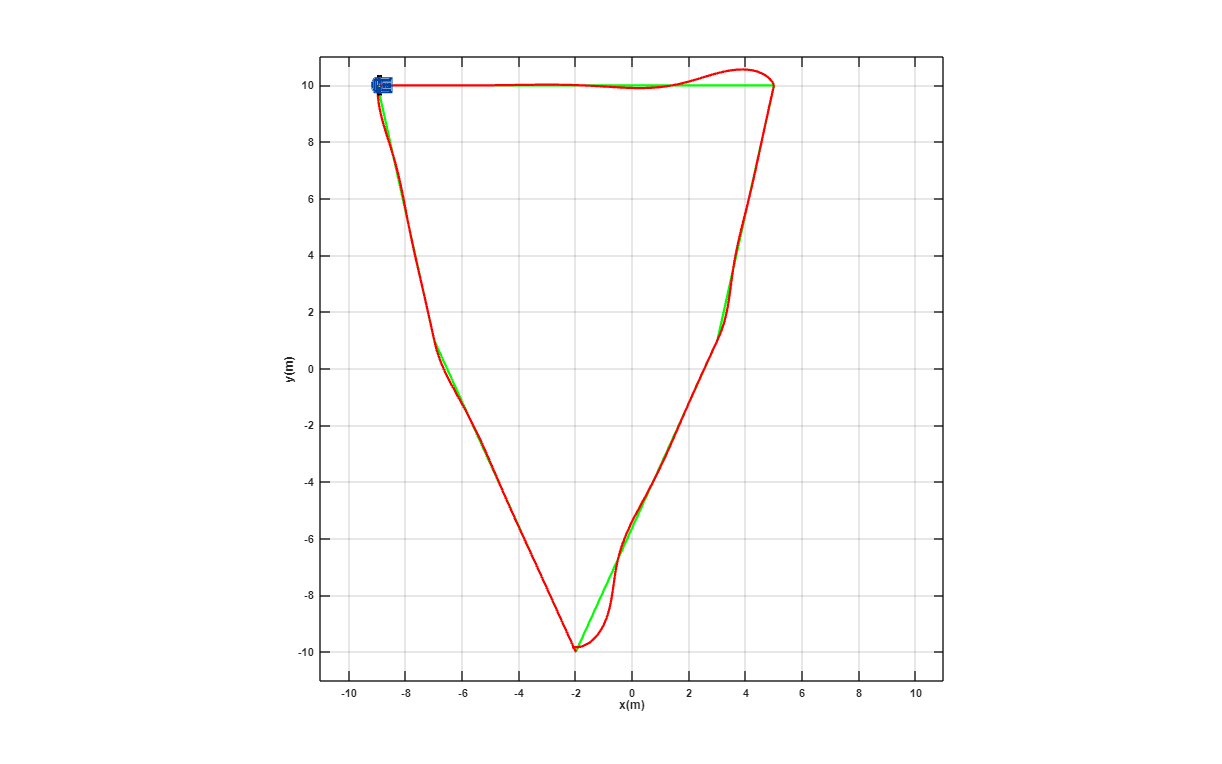

% Limpieza del entorno de trabajo
clear all
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf = 6;              % Tiempo total de simulación (segundos)
ts = 0.009;          % Tiempo de muestreo (segundos)
t = 0:ts:tf;         % Vector de tiempo
N = length(t);       % Número total de muestras

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%
x1(1) = -9;          % Posición inicial en el eje X (m)
y1(1) = 10;          % Posición inicial en el eje Y (m)
phi(1) = 4.712389;   % Orientación inicial del robot (rad)

% El punto de control inicia en la misma posición que el robot
hx(1) = x1(1);       % Coordenada X del punto de control
hy(1) = y1(1);       % Coordenada Y del punto de control

%%%%%%%%%%%%%%%%%%%%%%%%%%%% COORDENADAS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Coordenadas de los vértices del hexágono
coord_x = [-9, -7, -2, 3, 5, -9];
coord_y = [10, 1, -10, 1, 10, 10];
num_puntos = length(coord_x);  

segment_time = tf / (num_puntos - 1);  % Tiempo dedicado a cada segmento de la trayectoria

hxd = zeros(1, N);
hyd = zeros(1, N);


for i = 1:num_puntos - 1
    idx = (t >= (i - 1) * segment_time) & (t < i * segment_time); 
    dt = t(idx) - (i - 1) * segment_time;                         
    dur = segment_time;

    % Interpolación lineal entre puntos
    hxd(idx) = coord_x(i) + (coord_x(i + 1) - coord_x(i)) / dur * dt;
    hyd(idx) = coord_y(i) + (coord_y(i + 1) - coord_y(i)) / dur * dt;
end

% Asignación explícita del último punto
hxd(t >= (num_puntos - 1) * segment_time) = coord_x(end);
hyd(t >= (num_puntos - 1) * segment_time) = coord_y(end);

hxdp = [diff(hxd) 0] / ts;
hydp = [diff(hyd) 0] / ts;

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for k = 1:N
    % a) Cálculo del error de posición en el punto de control
    hxe(k) = hxd(k) - hx(k);
    hye(k) = hyd(k) - hy(k);
    he = [hxe(k); hye(k)];  % Vector de error
    Error(k) = norm(he);    % Magnitud del error (euclideano)

    % b) Matriz de rotación (Jacobiana) del robot móvil
    J = [cos(phi(k)) -sin(phi(k));
         sin(phi(k))  cos(phi(k))];

    % c) Matriz de ganancias proporcionales del controlador
    K = [13 0;
         0 13];

    % d) Vector de velocidades deseadas del punto de control
    hdp = [hxdp(k); hydp(k)];

    % e) Ley de control: se suma la realimentación proporcional al vector de velocidades deseadas
    qpRef = pinv(J) * (hdp + K * he);

    % f) Cálculo de velocidades de entrada al robot
    v(k) = qpRef(1);  % Velocidad lineal
    w(k) = qpRef(2);  % Velocidad angular

    %% 5. APLICACIÓN DEL CONTROL (ACTUALIZACIÓN DE ESTADOS)
    % a) Integración de la velocidad angular para actualizar la orientación
    phi(k+1) = phi(k) + w(k) * ts;

    % b) Aplicación del modelo cinemático (robot diferencial)
    xp1 = v(k) * cos(phi(k));  % Componente X de la velocidad
    yp1 = v(k) * sin(phi(k));  % Componente Y de la velocidad

    % c) Integración de la velocidad lineal para actualizar la posición
    x1(k+1) = x1(k) + ts * xp1;
    y1(k+1) = y1(k) + ts * yp1;

    % d) Actualización del punto de control
    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end

%% 6. VISUALIZACIÓN 3D DEL MOVIMIENTO DEL ROBOT
scene = figure;
set(scene, 'Color', 'white');
set(gca, 'FontWeight', 'bold');
sizeScreen = get(0, 'ScreenSize');
set(scene, 'position', sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)');
ylabel('y(m)');
zlabel('z(m)');
view([-0.1 90]);  % Vista superior
axis([-11 11 -11 11 0 2]);  % Límites de la escena

% Cargar y graficar el robot en la posición inicial
scale = 4;
MobileRobot_5;  % Script externo que define el modelo del robot
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;

% Graficar trayectorias
H2 = plot3(hx(1), hy(1), 0, 'r', 'lineWidth', 2);          
H3 = plot3(hxd, hyd, zeros(1,N), 'g', 'lineWidth', 2);     

% Bucle para animación del movimiento del robot
step = 1;
for k = 1:step:N
    delete(H1);    
    delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);        
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'lineWidth', 2);
    pause(ts);
end

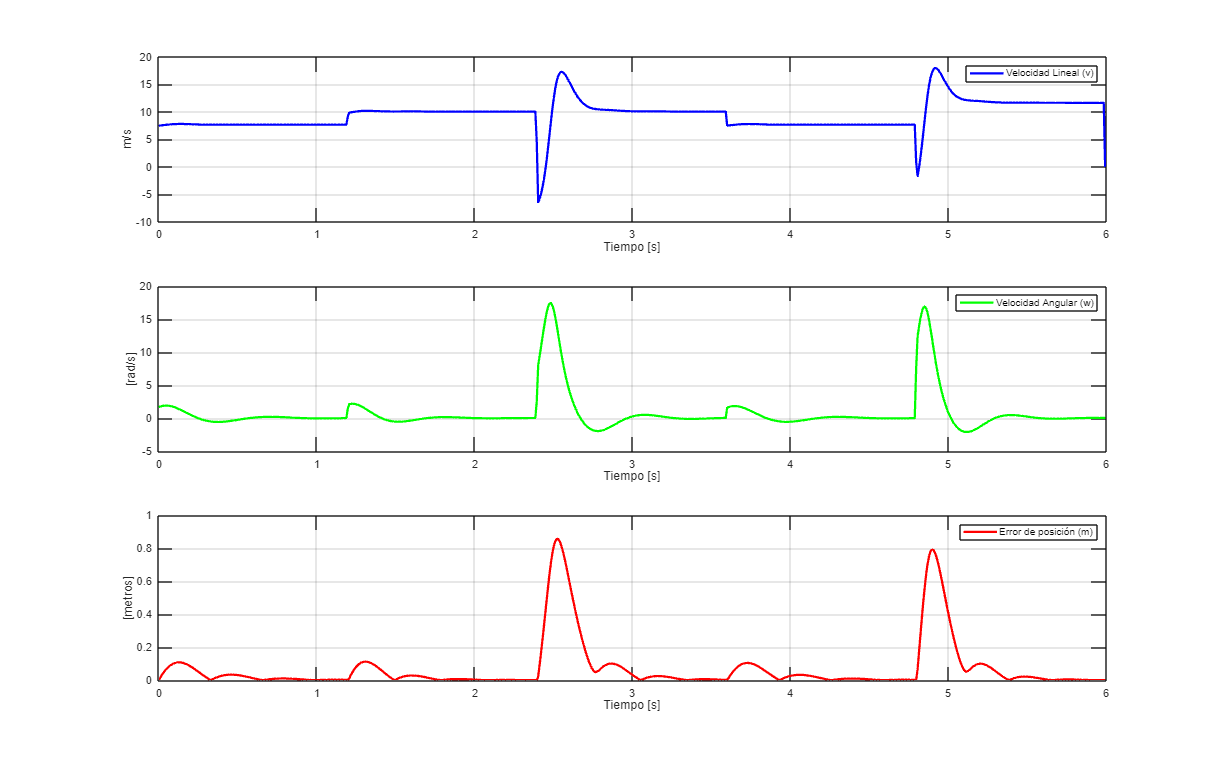


%% 7. GRÁFICAS DE RESULTADOS
graph = figure;
set(graph, 'position', sizeScreen);

subplot(311)
plot(t, v, 'b', 'LineWidth', 2);
grid on;
xlabel('Tiempo [s]');
ylabel('m/s');
legend('Velocidad Lineal (v)');

subplot(312)
plot(t, w, 'g', 'LineWidth', 2);
grid on;
xlabel('Tiempo [s]');
ylabel('[rad/s]');
legend('Velocidad Angular (w)');

subplot(313)
plot(t, Error, 'r', 'LineWidth', 2);
grid on;
xlabel('Tiempo [s]');
ylabel('[metros]');
legend('Error de posición (m)');

# Lazo abierto 

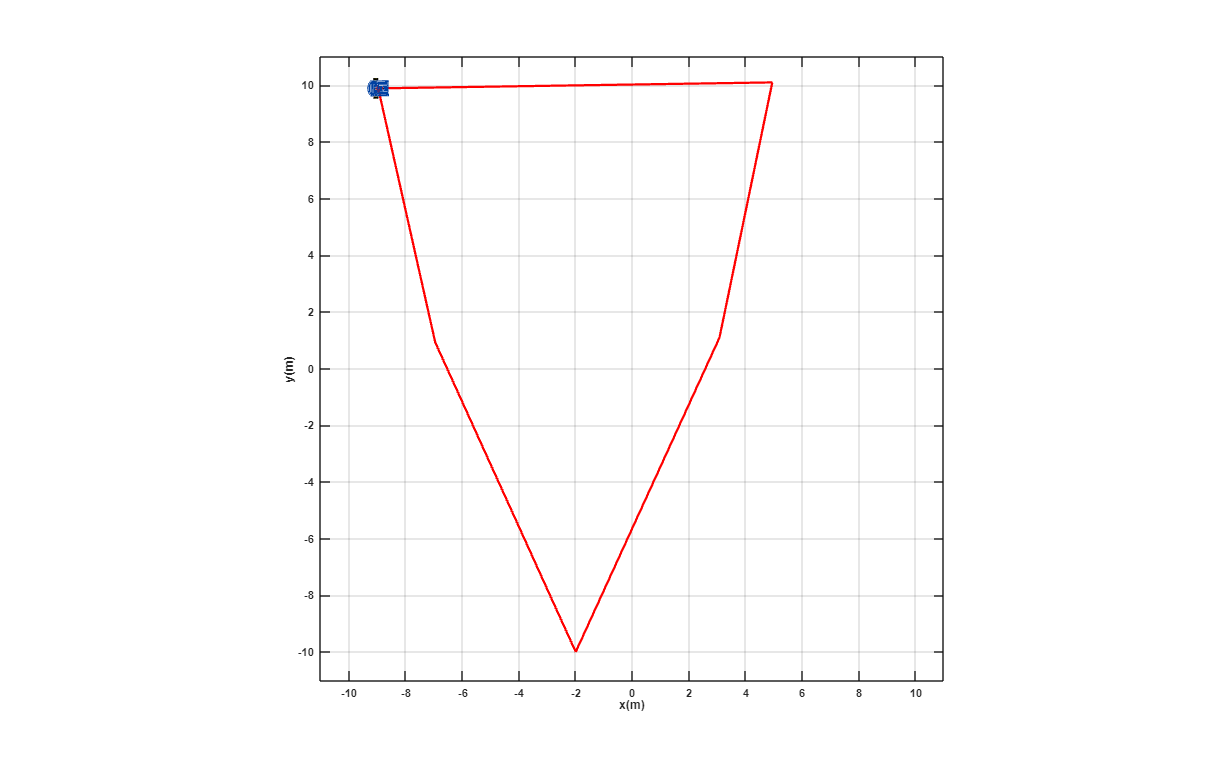

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Definición de parámetros de simulación
tf = 10;             % Tiempo de simulación en segundos
ts = 0.2;            % Tiempo de muestreo en segundos
t = 0:ts:tf;         % Vector de tiempo
N = length(t);       % Número total de muestras

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Inicialización de las variables de posición y orientación del robot
x1 = zeros(1, N+1);  % Posición eje x del robot
y1 = zeros(1, N+1);  % Posición eje y del robot
phi = zeros(1, N+1); % Orientación del robot en radianes

% Condiciones iniciales específicas
x1(1) = -9;          % Posición inicial en x
y1(1) = 10;          % Posición inicial en y
phi(1) = 0;          % Orientación inicial

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Inicialización del punto de control del robot (igual a la posición del robot)
hx = zeros(1, N+1);
hy = zeros(1, N+1);
hx(1) = x1(1);
hy(1) = y1(1);

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%
% Definición de las velocidades lineal (u) y angular (w) en cada instante
% Estas secuencias están diseñadas para generar un patrón tipo "zigzag"
u = [  0*ones(1,5), 9.3*ones(1,5), 0*ones(1,5), 12.0*ones(1,5), ...
       0*ones(1,5), 12.2*ones(1,5), 0*ones(1,5), 9.2*ones(1,5), ...
       0*ones(1,5), 14.0*ones(1,5), 0*ones(1,5)];

w = [-1.35*ones(1,5), 0*ones(1,5), 0.2053599*ones(1,5), 0*ones(1,5), ...
      2.2863*ones(1,5), 0*ones(1,5), 0.225*ones(1,5), 0*ones(1,5), ...
      1.79*ones(1,5), 0*ones(1,5), 0*ones(1,5)];

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Simulación del movimiento del robot mediante integración numérica (Euler)
for k = 1:N 
    % Actualización de la orientación del robot
    phi(k+1) = phi(k) + w(k) * ts;
    
    % Cálculo de la velocidad en el plano según el modelo cinemático
    xp1 = u(k) * cos(phi(k+1)); 
    yp1 = u(k) * sin(phi(k+1));

    % Actualización de la posición
    x1(k+1) = x1(k) + xp1 * ts;
    y1(k+1) = y1(k) + yp1 * ts;

    % Actualización de la posición del punto de control
    hx(k+1) = x1(k+1); 
    hy(k+1) = y1(k+1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%

% a) Configuración de la escena
scene = figure;                          % Crear figura
set(scene, 'Color', 'white');           % Fondo blanco
set(gca, 'FontWeight', 'bold');         % Ejes en negrita
sizeScreen = get(0, 'ScreenSize');      % Tamaño de la pantalla
set(scene, 'Position', sizeScreen);     % Ajustar figura al tamaño de pantalla
camlight('headlight');                  % Luz en la cámara
axis equal;                             % Escala uniforme en ejes
grid on; box on;                        % Mostrar cuadrícula y contorno
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([0 90]);                          % Orientación de la cámara
axis([-11 11 -11 11 0 1]);              % Límites del gráfico 3D

% b) Graficar robot en la posición inicial
scale = 4;                              % Escala para visualización del robot
MobileRobot_5;                          % Cargar modelo del robot (definido en otro script)
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;

% c) Graficar trayectoria inicial
H2 = plot3(hx(1), hy(1), 0, 'r', 'LineWidth', 2);

% d) Simulación de la animación del movimiento
step = 1;                               % Paso de la simulación visual

for k = 1:step:N
    delete(H1);    
    delete(H2);
    
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    
    pause(ts);                          % Pausa para simular tiempo real
end

# Lazo cerrado 

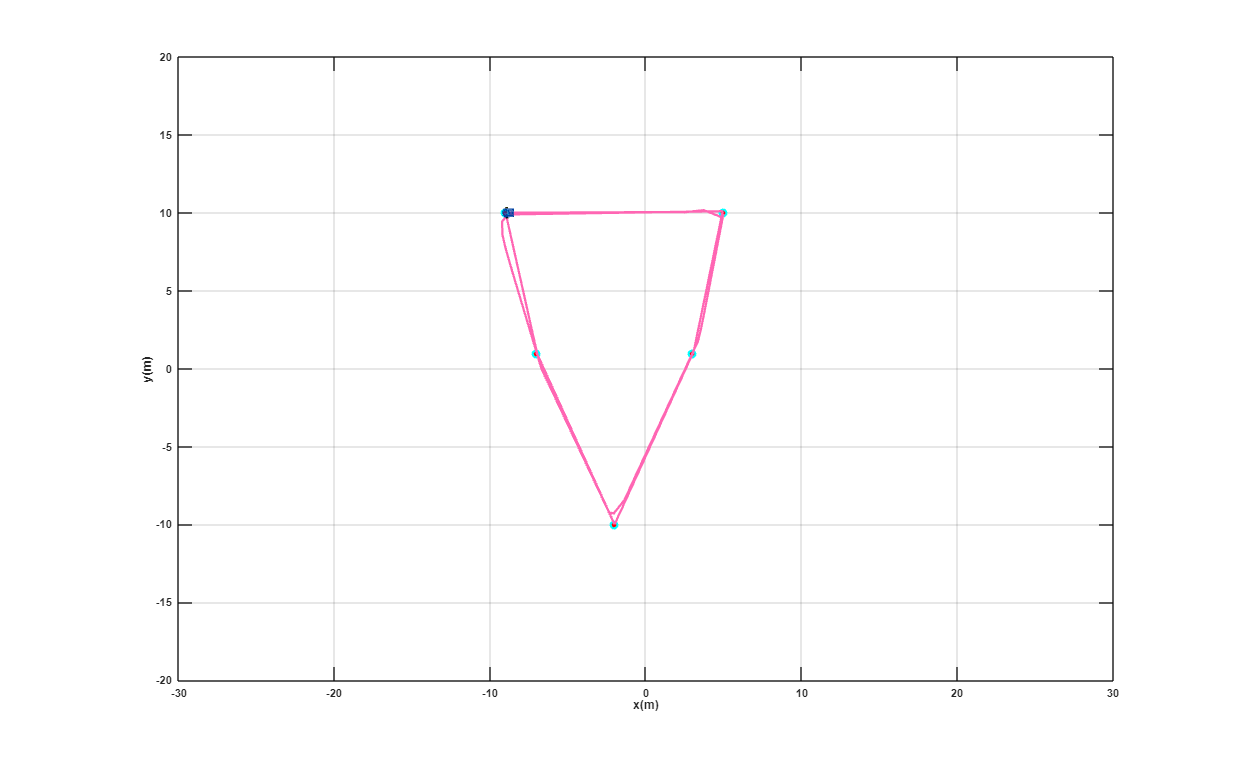

% ========================
% SIMULACIÓN DE MOVIMIENTO DE ROBOT MÓVIL DIFERENCIAL
% ========================

% ----- Condiciones iniciales del robot -----
x1(1) = -9;     % Posición inicial en x
y1(1) = 10;     % Posición inicial en y
phi(1) = -1.351213; % Orientación inicial en radianes
hx(1) = x1(1);  % Historial de x (trayectoria)
hy(1) = y1(1);  % Historial de y (trayectoria)

% ----- Puntos deseados a alcanzar en secuencia -----
coord = [  -7,  1;    % Punto 1
           -2, -10;   % Punto 2
            3,  1;    % Punto 3
            5,  10;   % Punto 4
           -9, 10];   % Punto 5 (mismo que el inicial, cierra ciclo)
       
% ----- Parámetros de tiempo -----
ts = 0.1;               % Tiempo de muestreo [s]
tf = 15;                % Tiempo final por cada objetivo [s]
N = floor(tf / ts);     % Número de iteraciones por objetivo
t_segment = linspace(0, tf, N); % Vector de tiempo por segmento

% ----- Preparar escena para animación -----
scale = 4;                          % Escala del robot para visualización
sizeScreen = get(0,'ScreenSize');   % Obtener tamaño de pantalla
scene = figure('Name','Animación trayectoria completa');
set(scene, 'Color','white', 'position', sizeScreen);
set(gca,'FontWeight','bold');
camlight('headlight');
axis equal; grid on; box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([0 90]);                       % Vista superior (XY)
axis([-30 30 -20 20 0 1]);          % Límites del gráfico

hold on;
plot(coord(:,1), coord(:,2), 'ro', 'MarkerFaceColor', 'r'); % Dibujar puntos deseados
plot3(x1(1), y1(1), 0, 'go', 'LineWidth', 2);                % Dibujar punto inicial

% ----- Dibujar robot e iniciar trayectoria -----
MobileRobot_5;                                      % Cargar modelo 3D (archivo externo)
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale);     % Dibujar robot en posición inicial
H2 = plot3(hx(1), hy(1), 0, 'Color', [1 0.4 0.7], 'LineWidth', 2); % Trayectoria

% ----- Inicializar acumuladores para gráficas finales -----
v_total = [];      % Velocidad lineal
w_total = [];      % Velocidad angular
error_total = [];  % Error de posición

% ----- Iterar sobre cada punto deseado -----
for i = 1:size(coord,1)
    hxd = coord(i,1); % Coordenada x del objetivo actual
    hyd = coord(i,2); % Coordenada y del objetivo actual

    % Inicializar señales por cada objetivo
    v = zeros(1,N); 
    w = zeros(1,N); 
    Error = zeros(1,N);

    for k = 1:N
        % ----- Cálculo del error de posición -----
        hxe = hxd - hx(end);  % Error en x
        hye = hyd - hy(end);  % Error en y
        he = [hxe; hye];      % Vector de error
        Error(k) = norm(he);  % Norma del error

        % ----- Cálculo de la Jacobiana (matriz de rotación) -----
        J = [cos(phi(end)) -sin(phi(end)); 
             sin(phi(end))  cos(phi(end))];

        % ----- Control proporcional con ganancia autoajustable -----
        Kp_base = 0.1;          % Ganancia mínima
        Kp_max = 1;             % Ganancia máxima
        Error_max = 2.0;        % Error para saturación
        error_norm = norm(he);  
        Kp_k = Kp_base + (Kp_max - Kp_base) * tanh(error_norm/Error_max); % Ganancia variable
        K = Kp_k * eye(2);      % Matriz de ganancias

        % ----- Cálculo de velocidades de referencia -----
        qpRef = pinv(J) * K * he; % Inversa pseudo de la Jacobiana para obtener v y w
        v(k) = qpRef(1);          % Velocidad lineal
        w(k) = qpRef(2);          % Velocidad angular

        % ----- Actualización del estado del robot -----
        phi(end+1) = phi(end) + w(k)*ts; % Nueva orientación
        xp1 = v(k)*cos(phi(end-1));      % Desplazamiento en x
        yp1 = v(k)*sin(phi(end-1));      % Desplazamiento en y
        x1(end+1) = x1(end) + xp1*ts;    % Nueva posición x
        y1(end+1) = y1(end) + yp1*ts;    % Nueva posición y
        hx(end+1) = x1(end);             % Guardar historial x
        hy(end+1) = y1(end);             % Guardar historial y
    end

    % ----- Acumular datos para graficar al final -----
    v_total = [v_total, v];
    w_total = [w_total, w];
    error_total = [error_total, Error];

    % ----- Animación del movimiento hacia el objetivo -----
    step = 5;  % Intervalo de actualización de animación
    for k = length(hx)-N+1 : step : length(hx)
        delete(H1); delete(H2); % Borrar dibujos anteriores
        H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale); % Dibujar robot
        len = min(length(hx), k);
        H2 = plot3(hx(1:len), hy(1:len), zeros(1,len), 'Color', [1 0.4 0.7], 'LineWidth', 2); % Dibujar trayectoria
        plot3(hxd, hyd, 0, 'co', 'LineWidth', 2); % Dibujar punto objetivo
        pause(ts); % Esperar para animación
    end
end

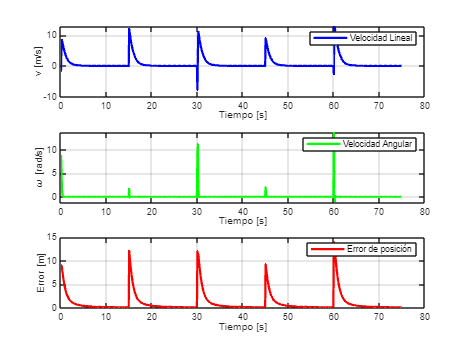


% ----- Graficar señales de control al finalizar -----
figure('Name','Variables de control');

subplot(311)
plot(ts*(0:length(v_total)-1), v_total, 'b', 'LineWidth', 2);
grid on; xlabel('Tiempo [s]'); ylabel('v [m/s]'); legend('Velocidad Lineal');

subplot(312)
plot(ts*(0:length(w_total)-1), w_total, 'g', 'LineWidth', 2);
grid on; xlabel('Tiempo [s]'); ylabel('\omega [rad/s]'); legend('Velocidad Angular');

subplot(313)
plot(ts*(0:length(error_total)-1), error_total, 'r', 'LineWidth', 2);
grid on; xlabel('Tiempo [s]'); ylabel('Error [m]'); legend('Error de posición');